# Coupled Circuits - Part V

## Inductively Coupled RLC circuits

Elisheva Nafha

warning('off','all')

Extract and fit sine to data

data_path_pattern = "./l_coupled_rlc_data/*KHz.csv";
paths = dir(data_path_pattern);

% Generate arrays for future sine fits, where f(t) = a * sin(b*t + c)
a_sent = zeros(length(paths), 1);
b_sent = zeros(length(paths), 1);
c_sent = zeros(length(paths), 1);

a_sent_err = zeros(length(paths), 1);
b_sent_err = zeros(length(paths), 1);
c_sent_err = zeros(length(paths), 1);

a_read_V1 = zeros(length(paths), 1);
b_read_V1 = zeros(length(paths), 1);
c_read_V1 = zeros(length(paths), 1);

a_read_V1_err = zeros(length(paths), 1);
b_read_V1_err = zeros(length(paths), 1);
c_read_V1_err = zeros(length(paths), 1);

a_read_V2 = zeros(length(paths), 1);
b_read_V2 = zeros(length(paths), 1);
c_read_V2 = zeros(length(paths), 1);

a_read_V2_err = zeros(length(paths), 1);
b_read_V2_err = zeros(length(paths), 1);
c_read_V2_err = zeros(length(paths), 1);

% to measure the oscilloscope's accuracy
d_osc = zeros(length(paths), 1);

frequencies = zeros(length(paths), 1);

% extract data, fit sine and calculate error
for i = linspace(1, length(paths), length(paths))
     frequencies(i) = str2double(paths(i).name(1:end - 7));
     data_path = sprintf("%s\\%s", paths(i).folder, paths(i).name);
     csv_recs = readtable(data_path);
     time = csv_recs.Var4;
     sent_signal = csv_recs.Var5;
     read_V1 = csv_recs.Var11;
     read_V2 = csv_recs.Var17;
     %plot(time, read_V);

     % fit sine to the sent data
     fitted_sine_sent = fit(time, sent_signal, 'sin1');
     a_sent(i) = fitted_sine_sent.a1;
     b_sent(i) = fitted_sine_sent.b1;
     c_sent(i) = fitted_sine_sent.c1;
     confint_sent = confint(fitted_sine_sent);
     a_sent_err(i) = (confint_sent(2, 1) - confint_sent(1, 1)) / 2;
     b_sent_err(i) = (confint_sent(2, 2) - confint_sent(1, 2)) / 2;
     c_sent_err(i) = (confint_sent(2, 3) - confint_sent(1, 3)) / 2;
     
     % fit sine to the read I1 data
     fitted_sine_read_V1 = fit(time, read_V1, 'sin1');
     a_read_V1(i) = fitted_sine_read_V1.a1;
     b_read_V1(i) = fitted_sine_read_V1.b1;
     c_read_V1(i) = fitted_sine_read_V1.c1;
     confint_read_V1 = confint(fitted_sine_read_V1);
     a_read_V1_err(i) = (confint_read_V1(2, 1) - confint_read_V1(1, 1)) / 2;
     b_read_V1_err(i) = (confint_read_V1(2, 2) - confint_read_V1(1, 2)) / 2;
     c_read_V1_err(i) = (confint_read_V1(2, 3) - confint_read_V1(1, 3)) / 2;

     % fit sine to the read I1 data
     fitted_sine_read_V2 = fit(time, read_V2, 'sin1');
     a_read_V2(i) = fitted_sine_read_V2.a1;
     b_read_V2(i) = fitted_sine_read_V2.b1;
     c_read_V2(i) = fitted_sine_read_V2.c1;
     confint_read_V2 = confint(fitted_sine_read_V2);
     a_read_V2_err(i) = (confint_read_V2(2, 1) - confint_read_V2(1, 1)) / 2;
     b_read_V2_err(i) = (confint_read_V2(2, 2) - confint_read_V2(1, 2)) / 2;
     c_read_V2_err(i) = (confint_read_V2(2, 3) - confint_read_V2(1, 3)) / 2;

end

Let us now extract voltage expected in L2:

We expect the inducted voltage's amplitude to go like $|\epsilon |\cdot \cos \left(\alpha \right)$:

R = 1e3;
L = 806e-3;
C = 200e-12;
w = frequencies;
V0 = a_sent;
alpha = 90 * 2 * pi / 360;
M = L * cos(alpha);
Z = sqrt(R^2 + (w.*L - 1 ./ (w*C)).^2);
delta = sqrt((R^2 + M^2 * L^2 - (w*L - 1./(w*C)).^2).^2 + 4*R^2 .* (w*L - 1./(w*C)).^2);
V1_pred = Z * R .* V0 ./ delta;
V2_pred = w * R .* M .* V0 ./ delta;


$$\Delta R=3,\;\Delta L={10}^{-2} ,\Delta C={10}^{-11}$$



$$\begin{array}{l}
\Delta \alpha =2\\
\Delta M=\sqrt{{\cos \left(\alpha \right)}^2 \cdot \Delta L^2 +L^2 \cdot {\sin \left(\alpha \right)}^2 \cdot \Delta \alpha^2 }\\
\Delta Z=\sqrt{{\left(\frac{\partial }{\partial R}Z\cdot \Delta R\right)}^2 +{\left(\frac{\partial }{\partial L}Z\cdot \Delta L\right)}^2 +{\left(\frac{\partial }{\partial C}Z\cdot \Delta C\right)}^2 }=\\
=\sqrt{{\left(\frac{R\cdot \Delta R}{\sqrt{R^2 +{\left(\omega L-\frac{1}{\omega C}\right)}^2 }}\right)}^2 +{\left(\frac{\left(\omega L-\frac{1}{\omega C}\right)\omega \cdot \Delta L}{\sqrt{R^2 +{\left(\omega L-\frac{1}{\omega C}\right)}^2 }}\right)}^2 +{\left(\frac{\left(\omega L-\frac{1}{\omega C}\right)\frac{1}{\omega C^2 }\cdot \Delta C}{\sqrt{R^2 +{\left(\omega L-\frac{1}{\omega C}\right)}^2 }}\right)}^2 }
\end{array}$$



$$\begin{array}{l}
\Delta |\Delta |=\Delta \sqrt{{\left(R^2 +M^2 L^2 -{\left(\omega L-\frac{1}{\omega C}\right)}^2 \right)}^2 +4R^2 {\left(\omega L-\frac{1}{\omega C}\right)}^2 }=\\
=\sqrt{{\left(\frac{\partial }{\partial R}|\Delta |\cdot \Delta R\right)}^2 +{\left(\frac{\partial }{\partial M}|\Delta |\cdot \Delta M\right)}^2 +{\left(\frac{\partial }{\partial L}|\Delta |\cdot \Delta L\right)}^2 +{\left(\frac{\partial }{\partial C}|\Delta |\cdot \Delta C\right)}^2 }=\\
={\left(\left(4R\left(R^2 +M^2 L^2 +{\left(\omega L-\frac{1}{\omega C}\right)}^2 \right)\cdot \Delta R\right)\right.}^2 +{\left(4ML^2 \left(R^2 +M^2 L^2 -{\left(\omega L-\frac{1}{\omega C}\right)}^2 \right)\cdot \Delta M\right)}^2 \\
+{\left(\left(\left(2\left(R^2 +M^2 L^2 -{\left(\omega L-\frac{1}{\omega C}\right)}^2 \right)\left(M^2 L-2\omega \left(\omega L-\frac{1}{\omega C}\right)\right)+8\omega R^2 \left(\omega L-\frac{1}{\omega C}\right)\right)\cdot \Delta L\right.\right)}^2 +\\
{\left(\left(\left(-\frac{4}{\omega C^2 }\left(\omega L-\frac{1}{\omega C}\right)\left(R^2 +M^2 L^2 -{\left(\omega L-\frac{1}{\omega C}\right)}^2 \right)-8\frac{R^2 }{\omega C^2 }\left(\omega L-\frac{1}{\omega C}\right)\right)\cdot \Delta C\right.\right)}^2 {\left.\right)}^{\frac{1}{2}} 
\end{array}$$



$$\Delta V_1 =\Delta \left(\frac{{|Z|\textrm{RV}}_0 }{|\Delta |}\right)=\sqrt{{\left(\frac{{\textrm{RV}}_0 }{|\Delta |}\cdot \Delta Z\right)}^2 +{\left(\frac{{|Z|V}_0 }{|\Delta |}\cdot \Delta R\right)}^2 +{\left(\frac{|Z|R}{|\Delta |}\cdot \Delta V_0 \right)}^2 +{\left(-\frac{{|Z|\textrm{RV}}_0 }{{|\Delta |}^2 }\cdot \Delta |\Delta |\right)}^2 }$$



$$\Delta V_2 =\Delta \left(\frac{{\omega \textrm{RMV}}_0 }{|\Delta |}\right)=\sqrt{{\left(\frac{\omega {\textrm{MV}}_0 }{|\Delta |}\cdot \Delta R\right)}^2 +{\left(\frac{{\omega \textrm{RV}}_0 }{|\Delta |}\cdot \Delta M\right)}^2 +{\left(\frac{\omega \textrm{MR}}{|\Delta |}\cdot \Delta V_0 \right)}^2 +{\left(-\frac{{\omega \textrm{MRV}}_0 }{{|\Delta |}^2 }\cdot \Delta |\Delta |\right)}^2 }$$


d_R = 0;
d_L = 0;
d_C = 0;
d_a = 2;
d_V0 = a_sent_err;
iZ = w*L - 1/(w*C);
delta1 = R^2 + M.^2 * L^2 - iZ^2;
d_M = sqrt(cos(alpha).^2 * d_L^2 + L^2 * sin(alpha).^2 * d_a^2);
d_Z = sqrt((R * d_R ./ Z).^2 + (iZ .* w * d_L ./ Z).^2 + (iZ ./ (w * C^2) * d_C ./ Z).^2);
d_Delta_d_R = 4 * R * (R^2 + M^2 * L^2 + iZ.^2);
d_Delta_d_M = 4 * M * L^2 .* delta1;
d_Delta_d_L = 2 * delta1 .* (M.^2 * L - 2 * w .* iZ) + 8 * w * R^2 .* iZ;
d_Delta_d_C = -4 ./ (w * C^2) .* iZ .* delta1 -8 * R^2 ./ (w * C^2) .* iZ;
d_Delta = sqrt((d_Delta_d_R * d_R).^2 + (d_Delta_d_M .* d_M).^2 + (d_Delta_d_L * d_L).^2 + (d_Delta_d_C * d_C).^2);
d_V1 = sqrt((R * V0 ./ delta .* d_Z).^2 + (Z .* V0 ./ delta * d_R).^2 + (Z * R ./ delta .* d_V0).^2 + (Z * R .* V0 ./ delta.^2 .* d_Delta).^2);
d_V2 = sqrt((w * M .* V0 ./ delta * d_R).^2 + (w * R .* V0 ./ delta .* d_M).^2 + (w * M * R ./ delta .* d_V0).^2 + (w * M * R .* V0 ./ delta.^2 .* d_Delta).^2);

Calculate measures errorbar:

d_osc = 0.1589;
d_read_v1 = sqrt(a_read_V1_err.^2 + d_osc^2);
d_read_v2 = sqrt(a_read_V2_err.^2 + d_osc^2);

Lets plot

figure()
subplot(1, 2, 1);
hold on
expected_V1 = errorbar(w, V1_pred, d_V1, 'LineStyle','none','Marker','.', 'MarkerSize', 15, 'Color', 'Blue');
measured_V1 = errorbar(w, a_read_V1, d_read_v1, 'LineStyle','none','Marker','.', 'MarkerSize', 15, 'Color', 'Red');
% degrees_spect = linspace(min(degrees), max(degrees), 1000);
% fitted_V1 = plot(degrees_spect, b(1) * sin(degrees_spect * 2 * pi / 360 + b(2)), 'Color', 'Blue');
title("Measured Voltage Over Circuit I", Interpreter="latex")
xlabel("Angle $\alpha$ (deg)", Interpreter="latex")
ylabel("Voltage (V)", Interpreter="latex")
h = [measured_V1, expected_V1];
legend(h, 'Measured $V_{tot}$', 'Predicted $V_{tot}$', 'interpreter','latex')
hold off

subplot(1, 2, 2);
hold on
expected_V2 = errorbar(w, V2_pred, d_V2, 'LineStyle','none','Marker','.', 'MarkerSize', 15, 'Color', 'Blue');
measured_V2 = errorbar(w, a_read_V2, d_read_v2, 'LineStyle','none','Marker','.', 'MarkerSize', 15, 'Color', 'Red');
% degrees_spect = linspace(min(degrees), max(degrees), 1000);
% fitted_V1 = plot(degrees_spect, b(1) * sin(degrees_spect * 2 * pi / 360 + b(2)), 'Color', 'Blue');
title("Measured Voltage Over Circuit II", Interpreter="latex")
xlabel("Angle $\alpha$ (deg)", Interpreter="latex")
ylabel("Voltage (V)", Interpreter="latex")
h = [measured_V2, expected_V2]

h =   1×41 ErrorBar array:

  Columns 1 through 29

    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar

  Columns 30 through 41

    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar    ErrorBar


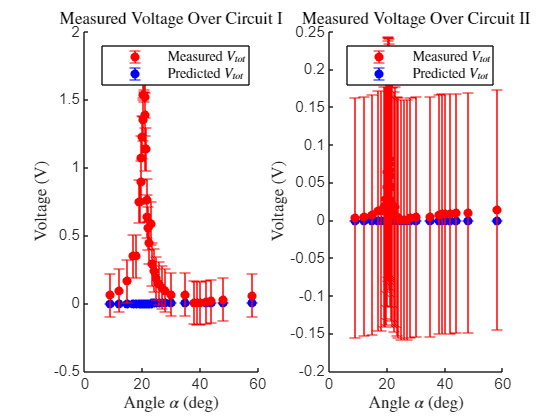

legend(h, 'Measured $V_{tot}$', 'Predicted $V_{tot}$', 'interpreter','latex')
hold off

function std = std_given_mean(data, mean)
    N = length(data);
    std = sqrt(sum((data - mean).^2) / (N - 1));
end

function data_crit_pts = find_discrete_sine_critical_points(time, voltage, a,  w, phi)
    % find critical points analytically    
    syms t real;
    f = a * sin(w * t + phi);
    df = matlabFunction(diff(f, t));
    f = matlabFunction(f);
    crit_pts_indices = find(gradient(sign(df(time)))~=0);
    crit_pts = round(mean(reshape(time(crit_pts_indices),2,[])), 5);

    % find the critical points in the data
    data_crit_pts = voltage(crit_pts_indices);
end

function fit_DC_coupled(time, voltage, initial_guess)
    start_idx = find(time > 0, 1, "first")
    tbl = table(time(start_idx:end), voltage(start_idx:end));
    modelfun = @(b,x) b(1) * exp(-b(2)*x) .* cos((b(3) + b(4)) / 2 * x) .* cos((b(3) - b(4)) / 2 * x);
    beta0 = initial_guess;
    % Now the next line is where the actual model computation is done.
    mdl = fitnlm(tbl, modelfun, beta0);
    b = mdl.Coefficients{:, 'Estimate'}
    SE = mdl.Coefficients{:, 'SE'}
    figure()
    hold on
    plot(time, voltage)
    title("Coupled RLC with DC and C_c=1.2nF", Interpreter="latex")
    xlabel("Voltage (V)", Interpreter="latex")
    ylabel("time (s)", Interpreter="latex")
    %plot(time, b(1) * exp(-b(2)*time) .* cos((b(3) + b(4)) / 2 * time) .* cos((b(3) - b(4)) / 2 * time))
    hold off
end

function plot_fit(time, signal, a, b, c)
    figure();
    hold on
    sine_fit = a * sin(b * time + c);
    scatter(time, signal);
    plot(time, sine_fit);
    title(sprintf("Sine Fit %d * sin(%d * t + %d)", a, b, c));
    hold off
end

